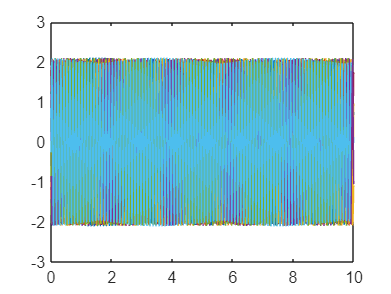

time_x = {senf020a200Ent_Time, senf060a200Ent_Time, senf500a200Ent_Time, senf550a200Ent_Time, senf600a200Ent_Time, senf650a200Ent_Time, senf700a200Ent_Time, senf750a200Ent_Time, senf800a200Ent_Time, senf850a200Ent_Time, senf900a200Ent_Time, senf950a200Ent_Time, senf1000a200Ent_Time};
time_y = {senf020a200Sai_Time(:,1), senf060a200Sai_Time(:,1), senf500a200Sai_Time(:,1), senf550a200Sai_Time(:,1), senf600a200Sai_Time(:,1), senf650a200Sai_Time(:,1), senf700a200Sai_Time(:,1), senf750a200Sai_Time(:,1), senf800a200Sai_Time(:,1), senf850a200Sai_Time(:,1), senf900a200Sai_Time(:,1), senf950a200Sai_Time(:,1), senf1000a200Sai_Time(:,1)};

x = {senf020a200Ent_Value, senf060a200Ent_Value, senf500a200Ent_Value, senf550a200Ent_Value, senf600a200Ent_Value, senf650a200Ent_Value, senf700a200Ent_Value, senf750a200Ent_Value, senf800a200Ent_Value, senf850a200Ent_Value, senf900a200Ent_Value, senf950a200Ent_Value, senf1000a200Ent_Value};
y = {senf020a200Sai_Value(:,1), senf060a200Sai_Value(:,1), senf500a200Sai_Value(:,1), senf550a200Sai_Value(:,1), senf600a200Sai_Value(:,1), senf650a200Sai_Value(:,1), senf700a200Sai_Value(:,1), senf750a200Sai_Value(:,1), senf800a200Sai_Value(:,1), senf850a200Sai_Value(:,1), senf900a200Sai_Value(:,1), senf950a200Sai_Value(:,1), senf1000a200Sai_Value(:,1)};


graf_init = 1;
graf_end = 13;

%201 -> 351
for i = graf_init:graf_end
    time_x{i}= time_x{i}-time_x{i}(1);
    plot(time_x{i},x{i})
    hold on
end
hold off

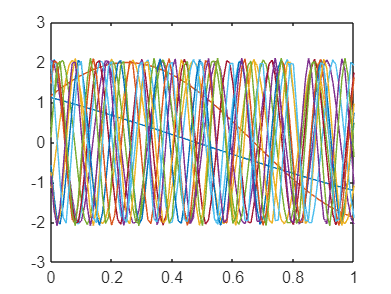

range_time_x = zeros(length(0:0.01:1), graf_end-graf_init+1);
range_x = zeros(length(0:0.01:1), graf_end-graf_init+1);

for i = graf_init:graf_end
    for j = 0:100
        range_time_x(j+1, i)= time_x{i}(length(time_x{i})-100+j)-time_x{i}(length(time_x{i})-100);
        range_x(j+1, i)= x{i}(length(time_x{i})-100+j);
    end
end

range_time_y = zeros(length(0:0.01:1), graf_end-graf_init+1);
range_y = zeros(length(0:0.01:1), graf_end-graf_init+1);

for i = graf_init:graf_end
    for j = 0:100
        range_time_y(j+1, i)= time_y{i}(length(time_y{i})-100+j)-time_y{i}(length(time_y{i})-100);
        range_y(j+1, i)= y{i}(length(time_y{i})-100+j);
    end
end

plot(range_time_x(:,:),range_x(:,:))

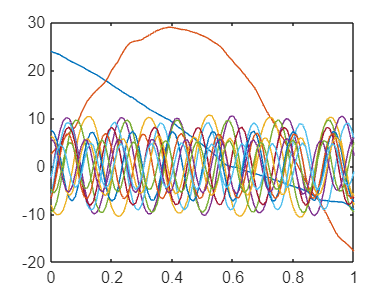

plot(range_time_y(:,:),range_y(:,:))

x_mx_fft = fft(range_x)

x_mx_fft =   -5.9822 + 0.0000i  59.0810 + 0.0000i  -1.2429 + 0.0000i   0.5222 + 0.0000i   0.4927 + 0.0000i   3.7459 + 0.0000i   1.9831 + 0.0000i  -7.6515 + 0.0000i   1.8525 + 0.0000i  -6.3099 + 0.0000i  -1.1630 + 0.0000i   6.1700 + 0.0000i   2.3602 + 0.0000i
   1.4562 -39.2691i -31.8037 -77.6826i  -1.2828 - 0.4090i   0.4737 + 2.1192i   0.5186 - 0.3539i   3.7882 + 1.4805i   2.0279 - 0.1149i  -7.7704 - 0.6242i   1.8864 - 0.1243i  -6.3805 - 0.5818i  -1.1925 + 0.1971i   6.2313 + 0.2809i   2.3783 + 0.1539i
   1.2428 -19.0167i  -4.4838 -27.0671i  -1.4251 - 0.9312i   0.3066 + 4.7050i   0.6057 - 0.7718i   3.9280 + 3.1838i   2.1742 - 0.2440i  -8.1539 - 1.3172i   1.9947 - 0.2600i  -6.6045 - 1.2125i  -1.2563 + 0.3935i   6.4234 + 0.5805i   2.4351 + 0.3166i
   1.2037 -12.5859i  -0.9482 -17.0433i  -1.7773 - 1.8164i  -0.0731 + 8.6493i   0.7929 - 1.3640i   4.2153 + 5.4630i   2.4651 - 0.4087i  -8.8978 - 2.1770i   2.2006 - 0.4227i  -7.0237 - 1.9560i  -1.3816 + 0.6267i   6.7737 + 0.9218i   2.5378 + 0.498

y_mx_fft = fft(range_y)

y_mx_fft = 1.0e+03 *

   0.5891 + 0.0000i   1.3350 + 0.0000i  -0.0105 + 0.0000i   0.0555 + 0.0000i  -0.0123 + 0.0000i   0.0325 + 0.0000i  -0.0080 + 0.0000i  -0.0010 + 0.0000i  -0.0087 + 0.0000i  -0.0013 + 0.0000i   0.0089 + 0.0000i  -0.0108 + 0.0000i  -0.0018 + 0.0000i
   0.0981 - 0.5859i  -0.7964 - 0.5086i  -0.0159 - 0.0037i   0.0613 - 0.0002i  -0.0107 - 0.0004i   0.0355 - 0.0040i  -0.0078 - 0.0007i   0.0017 + 0.0042i  -0.0073 + 0.0000i  -0.0017 + 0.0012i   0.0101 - 0.0020i  -0.0075 - 0.0018i  -0.0002 - 0.0011i
   0.0147 - 0.2520i  -0.1215 - 0.1880i   0.0037 + 0.0044i   0.0695 - 0.0081i  -0.0111 - 0.0005i   0.0401 - 0.0067i  -0.0083 - 0.0023i   0.0022 + 0.0094i  -0.0077 - 0.0028i   0.0016 + 0.0127i   0.0087 - 0.0009i  -0.0107 - 0.0035i   0.0000 - 0.0008i
   0.0209 - 0.1937i  -0.0293 - 0.1020i  -0.0154 - 0.0011i   0.0869 + 0.0055i  -0.0109 - 0.0012i   0.0437 - 0.0112i  -0.0081 - 0.0040i   0.0022 + 0.0153i  -0.0078 - 0.0023i   0.0059 + 0.0070i   0.0105 + 0.0006i  -0.0149 - 0.0071i  -0.0


P2 = abs(y_mx_fft./(graf_end-graf_init+1));
P1 = P2(1:floor(N/2)+1,:);
P1(2:end-1) = 2*P1(2:end-1);

(0:(N/2))

ans =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49



plot(frequencies,P1(:,1),'m')

Error using plot
Vectors must be the same length.

title("Single-Sided Amplitude Spectrum of output(t)")
xlabel("f (Hz)")
ylabel("|P1(f)|")

H_mx = y_mx_fft./x_mx_fft

magnitudeResponse2 = zeros(1,graf_end-graf_init+1);
phaseResponse2 = zeros(1,graf_end-graf_init+1);

for i = graf_init:graf_end
    [magnitudeResponse2(i),  index]= max(abs(H_mx(:,i)));
    phaseResponse2(i) = rad2deg(angle(H(index, i)));
end


%pegando as frequências medidas
%frequencySample
frequencies = [0.2, 0.6, 5, 5.5, 6, 6.5, 7, 7.5, 8, 8.5, 9, 9.5, 10];

omega2 = zeros(1, graf_end-graf_init+1);
ampl2 = zeros(1, graf_end-graf_init+1);


for i = graf_init:graf_end
    omega2(i) = 2*pi*frequencies(i);
    ampl2(i) = 20*log10(magnitudeResponse2(i));
end

semilogx(omega2,ampl2,'-')
grid on

fase2 = zeros(1, graf_end-graf_init+1);

for i = graf_init:graf_end
    fase2(i) = phaseResponse2(i);
end

semilogx(omega2, fase2)
grid on

x_fft = cell(1,graf_end-graf_init+1);
y_fft = cell(1,graf_end-graf_init+1);

for i = graf_init:graf_end
    x_fft{i} = fft(x{i});
    y_fft{i} = fft(y{i});
end

H = cell(1,graf_end-graf_init+1);

for i = graf_init:graf_end
    H{i} = y_fft{i}./x_fft{i};
end

%pegando as frequências medidas
%frequencySample
frequencies = [0.2, 0.6, 2, 5, 5.5, 6, 6.5, 7, 7.5, 8, 8.5, 9, 9.5, 10];

magnitudeResponse = zeros(1,graf_end-graf_init+1)
phaseResponse = cell(1,graf_end-graf_init+1);

for i = graf_init:graf_end
    [magnitudeResponse(i),  index]= max(abs(H{i}));
    phaseResponse{i} = rad2deg(angle(H{i}(index)));
end
figure;

omega = zeros(graf_end-graf_init+1);
ampl = zeros(graf_end-graf_init+1);

for i = graf_init:graf_end
    omega(i) = 2*pi*frequencies(i);
    ampl(i) = 20*log10(magnitudeResponse(i));
end

semilogx(omega,ampl,'-')
grid on

fase = zeros(graf_end-graf_init+1);

for i = graf_init:graf_end
    fase(i) = phaseResponse{i};
end

semilogx(omega, fase)
grid on
